# HW4

## Task 1

%% Differential Equation
% Fg - Fdrag = ma
% mg - kv^2 = m dv/dt
% rearrange 
% dv/dt = g - (k/m)*v^2   % Differential Equation

syms v(t) g m k 

% Differential Equation
DE = diff(v,t) == g - (k/m)*v^2;

cond = v(0) == 0; % Initial condition: velocity is zero at t=0 
SOL(t) = dsolve(DE, cond); 
VELOCITY = matlabFunction(SOL);
VELOCITY

VELOCITY = function_handle with value:
    @(t,g,k,m)sqrt(g).*1.0./sqrt(k).*sqrt(m).*tanh(sqrt(g).*sqrt(k).*1.0./sqrt(m).*t)


% Constants
g0 = 10; % gravity
k0 = 1;  % drag coefficient

% Masses
masses = [1, 2, 5, 10];

%% Figure 1: Velocity vs. Time
figure;
hold on;
colors = {'b', 'r', 'g', 'k'};
legends = cell(1, length(masses));  % Pre-allocate cell array for legend entries

for i = 1:length(masses)
    m_i = masses(i);
    % Terminal velocity calculation
    VT = sqrt((m_i * g0) / k0);
    fprintf('VT(m=%d) = %6.2f\n', m_i, VT);
    
    % Plot velocity
    fplot(VELOCITY(t, g0, k0, m_i), [0, 30], 'LineWidth', 2, 'Color', colors{i});
    
    % Create legend entry
    legends{i} = sprintf('m=%d', m_i);
end

VT(m=1) =   3.16
VT(m=2) =   4.47
VT(m=5) =   7.07
VT(m=10) =  10.00


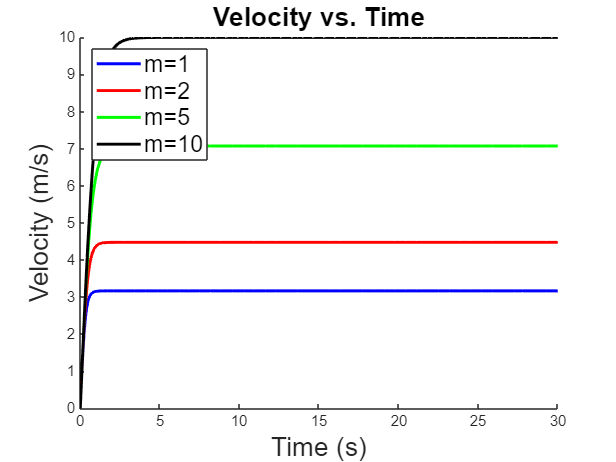


legend(legends, 'FontSize', 16, 'Location', 'northwest');
xlabel('Time (s)', 'FontSize', 18);
ylabel('Velocity (m/s)', 'FontSize', 18);
title('Velocity vs. Time', 'FontSize', 18);
saveas(gcf, 'Velocity_Quadratic.png');

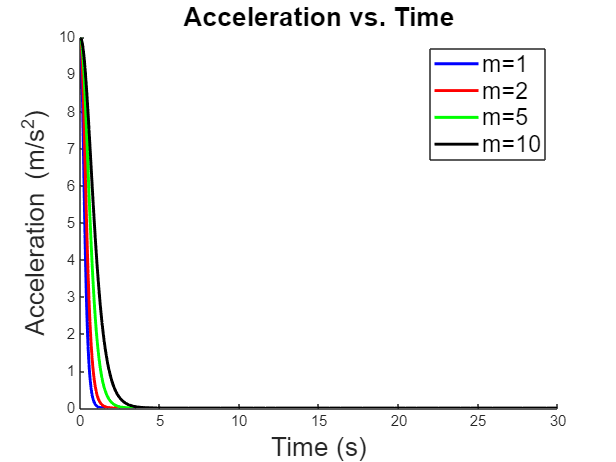


%% Figure 2: Acceleration vs. Time
SOL2 = diff(SOL, t); % Acceleration
acc = matlabFunction(SOL2);
figure;
hold on;
legends = cell(1, length(masses));  % Pre-allocate cell array for legend entries

for i = 1:length(masses)
    m_i = masses(i);
    fplot(acc(t, g0, k0, m_i), [0, 30], 'LineWidth', 2, 'Color', colors{i});
    
    % Create legend entry
    legends{i} = sprintf('m=%d', m_i);
end

legend(legends, 'FontSize', 16, 'Location', 'northeast');
xlabel('Time (s)', 'FontSize', 18);
ylabel('Acceleration (m/s^2)', 'FontSize', 18);
title('Acceleration vs. Time', 'FontSize', 18);
saveas(gcf, 'Acceleration_Quadratic.png');

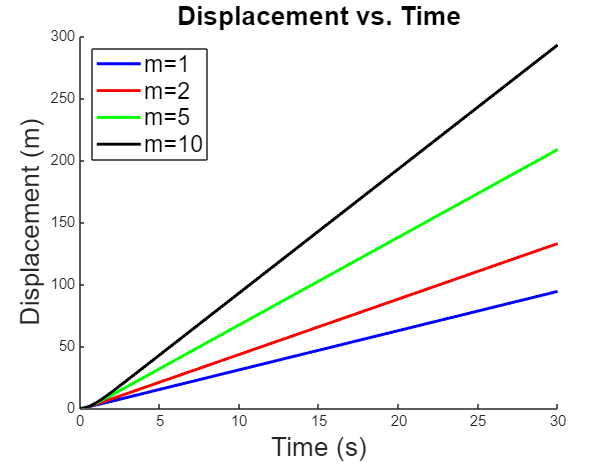


%% Displacement Calculation
dispY = int(VELOCITY, t); % Integrate velocity to get displacement
dispYfun = matlabFunction(dispY);  % Convert symbolic expression to function handle

% Figure 3: Displacement vs. Time for Different Masses
figure;
hold on;
legends = cell(1, length(masses));  % Pre-allocate cell array for legend entries

for i = 1:length(masses)
    m_i = masses(i);
    % Displacement with initial condition
    C = dispYfun(g0, k0, m_i, 0); % Displacement at t=0 is zero
    Y = @(t) dispYfun(g0, k0, m_i, t) - C;
    fplot(Y, [0, 30], 'LineWidth', 2, 'Color', colors{i});
    
    % Create legend entry
    legends{i} = sprintf('m=%d', m_i);
end

legend(legends, 'FontSize', 16, 'Location', 'northwest');
xlabel('Time (s)', 'FontSize', 18);
ylabel('Displacement (m)', 'FontSize', 18);
title('Displacement vs. Time', 'FontSize', 18);
saveas(gcf, 'Displacement_Quadratic_Drag.png');

## Task 2

for i = 1:length(masses)
    m_i = masses(i);
    
    % Terminal velocity calculation
    VT = sqrt((m_i * g0) / k0); % Terminal velocity
    half_VT = 0.5 * VT; % 50% of terminal velocity
    
    velocity_eq = subs(SOL, {g, k, m}, {g0, k0, m_i});
    
    % Solve for time when velocity is half of terminal velocity
    time_eq = velocity_eq == half_VT;
    time_to_half_VT = solve(time_eq, t);
    
    % Display result
    fprintf('Time to reach 50%% of terminal velocity for m=%d: %6.2f seconds\n', m_i, double(time_to_half_VT));
end

Time to reach 50% of terminal velocity for m=1:   0.17 seconds
Time to reach 50% of terminal velocity for m=2:   0.25 seconds
Time to reach 50% of terminal velocity for m=5:   0.39 seconds
Time to reach 50% of terminal velocity for m=10:   0.55 seconds
